# Программа подсчета коэффициентов по ареотерме

За стандартную полагается ареотерма из Bertka, Fei, 1997:

% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 2);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:B17";

% Specify column names and types
opts.VariableNames = ["Pressure_Bar", "Temperature_K"];
opts.VariableTypes = ["double", "double"];

% Import the data
Ar = readtable("/Users/astrobirf/Desktop/MARS/Programs/MARS_X/Perple_X/MATLAB Scripts/areoterm.xlsx", opts, "UseExcel", false);

% Clear temporary variables
clear opts

% Display results
Ar

Ar = 16×2 table
    Pressure_Bar    Temperature_K
    ____________    _____________

         20000          1400     
         30000          1475     
         40000          1550     
         50000          1625     
         70000          1750     
         80000          1800     
         90000          1850     
         1e+05          1900     
       1.1e+05          1940     
       1.3e+05          2000     
       1.4e+05          2025     
       1.5e+05          2040     
       1.9e+05          2070     
       2.1e+05          2075     
      2.25e+05          2079     
      2.35e+05          2080     


Далее посчитаем 

x = table2array(Ar(:,"Pressure_Bar"));
y = table2array(Ar(:,"Temperature_K"));
p = polyfit(x, y, 4)

p = 1.0e+03 *

    0.0000   -0.0000   -0.0000    0.0000    1.2401


Ниже укажем коэффициенты полинома, начиная со старшей степени:


$$T = pr_1 P^4 + pr_2 P^3 + pr_3 P^2 + pr_4 P + pr_5$$


pr = [4.278426e-19 -1.746166e-13 -1.774443e-9 8.085953e-3 1.240095e3];
yfit = polyval(p,x);
yrfit = polyval(pr,x);
err = max(abs((yrfit - yfit)./(yfit - y))*100)

err = 0.3009

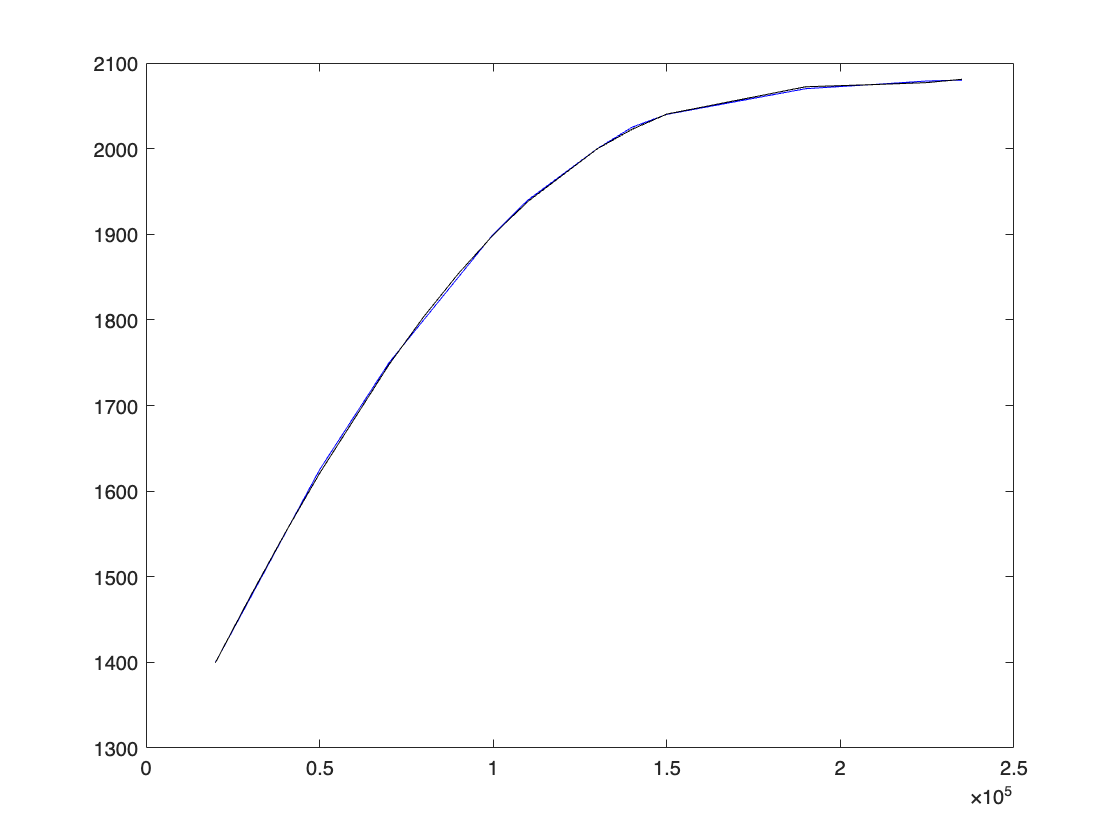

figure()
plot(x, y, 'b', x, yrfit, 'k')

### Проверка файла с данными ареотермы по точкам "mars_areoterm_dot.dat"

Загружаем файл

% Set up the Import Options and import the data
opts3 = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts3.DataLines = [1, Inf];
opts3.Delimiter = " ";

% Specify column names and types
opts3.VariableNames = ["Var1", "Var2"];
opts3.VariableTypes = ["double", "double"];

% Specify file level properties
opts3.ExtraColumnsRule = "ignore";
opts3.EmptyLineRule = "read";
opts3.LeadingDelimitersRule = "ignore";

% Import the data
areo = readtable("/Users/astrobirf/Desktop/MARS/Programs/MARS_X/Perple_X/mars_areoterm_dot.dat", opts3);

% Clear temporary variables
clear opts3

% Display results
areo

areo = 2500×2 table
    Var1     Var2 
    ____    ______

       1    1240.1
     101    1240.9
     201    1241.7
     301    1242.5
     401    1243.3
     501    1244.1
     601      1245
     701    1245.8
     801    1246.6
     901    1247.4
    1001    1248.2
    1101      1249
    1201    1249.8
    1301    1250.6
    1401    1251.4
    1501    1252.2


Создаем вектора точек

x1 = table2array(areo(:,"Var1"));
y1 = table2array(areo(:,"Var2"));

Создаем проверочный вектор по полиному и найдем максимальную разность

yr1fit = polyval(pr, x1);
err1 = max(abs(yr1fit-y1)./y1*100)

err1 = 0

И выведем все визуально

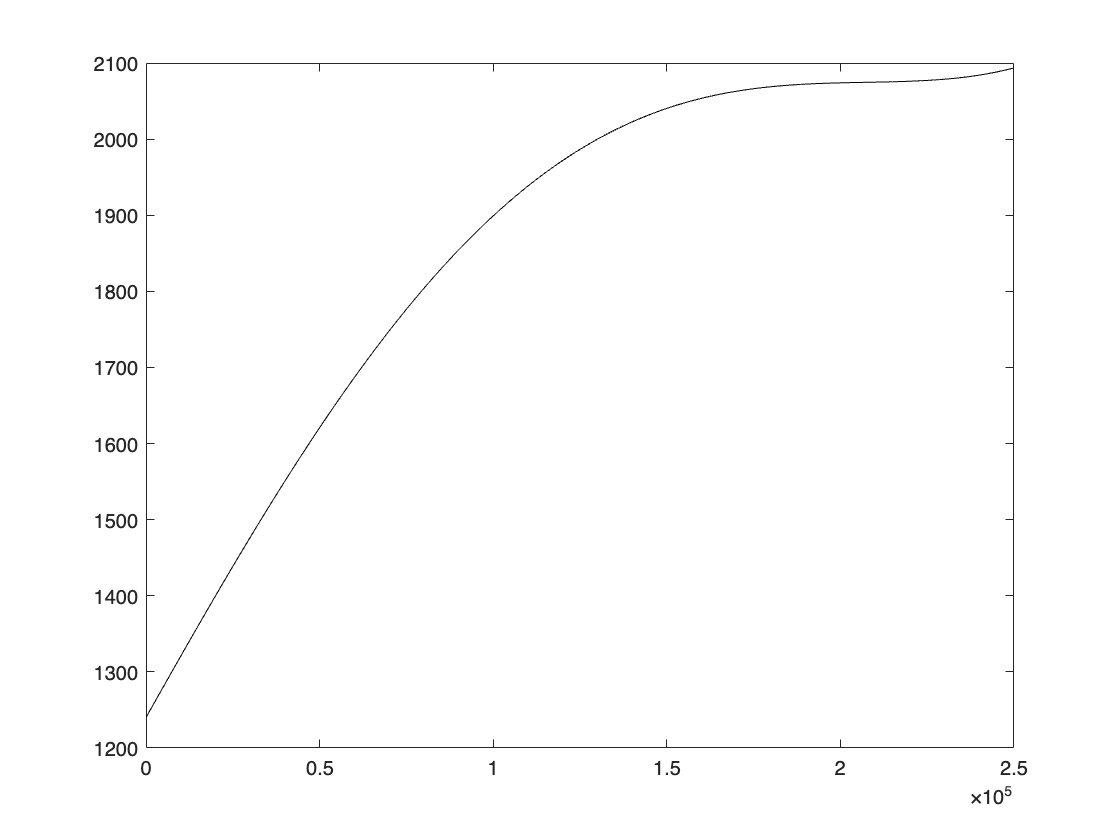

figure()
plot(x1, y1, 'r', x1, yr1fit, 'k')